Prepare parameter

% *** Load parameters from file
% This step would typically needs to be executed only once
%  Physical Description of the Catheter
FKParams.CathParams=Load_CRMCatheterModelParams_matlab('../catheterdata/CatheterParameterSet_2.txt');

Reading file: ../catheterdata/CatheterParameterSet_2.txt


%  Catheter Configuration in spatial coordinates
FKParams.CathConfig=Load_CatheterConfiguration_matlab('../catheterdata/CatheterSpatialConfiguration_1.txt');

Reading file: ../catheterdata/CatheterSpatialConfiguration_1.txt



% We will zero out ustar for simplifying geometry
FKParams.CathParams.ustar=[0, 0, 0; 0, 0, 0; 0, 0, 0];

% *** Other External variables
% specify if catheter is in free space or if the catheter tip is constrained to a contact point
FKParams.ContactMode = int8(0);  % 0: FREE_TIP;   1: FIXED_TIP
% External point force (in spatial coordinates) applied at the tip of the catheter (\lambda = 0)  - unit: ??
%   (this will be used when ContactMode == 0, FREE_TIP)
FKParams.TipForce = [ 0.0, 0.0, 0.0 ];
% The spatial coordinates of the point where the catheter tip is constrained to be 
%   (this will be used when ContactMode == ContactModeType::FIXED_TIP)
FKParams.TipConstraintPoint = [ 0.0, 0.0, 0.0 ];
% We want the localization coil locations, too
FKParams.FinalValueOnly = false; 

% *** Numerical Computation Parameters
% Stepsize used in numerical integration along the length of the catheter during IVP - unit: mm
FKParams.IntegrationStepSize = 0.2;
% Define initial guesses to be used when solving boundary value problem
% initial guess for the curvature at the catheter base
FKParams.deltau0_initialguess = [ 0.0, 0.0, 0.0 ];
% initial guess for the contstraint force at the catheter tip (this will be used when ContactMode == ContactModeType::FIXED_TIP)
FKParams.ftip_initialguess = [ 0.0, 0.0, 0.0 ];

% *** Control Inputs
% Inserted Length of the catheter (length of the catheter that is inside the heart chamber) - unit: mm
InsertedLength = 100.0;
% Actuation currents for each of the coils for each of the coil sets - unit: A
ActuationCurrents = [ 0.00, 0.00, 0.600, 0.00, 0.00, 0.600 ];
% pack them together into a single array
control_inputs = [ ActuationCurrents InsertedLength ];

Now let's start analysis. 

First, one dimensional:

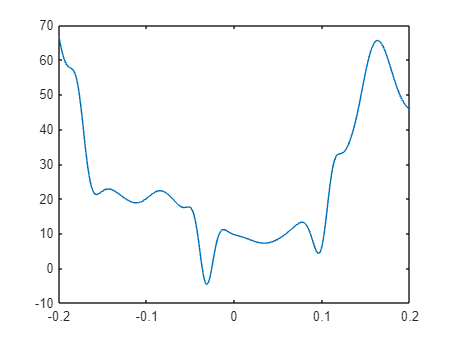

deltau0x=-0.2:0.001:0.2;
lx = length(deltau0x);
clear PE
PE(lx)=0;
for idx1=1:lx
    PE(idx1) = CRM_CalculateCatheterEnergy_matlab([deltau0x(idx1),0,0], FKParams.TipForce, control_inputs, FKParams);
end
plot(deltau0x,PE)

Now, three dimensiona;

deltau0x=-0.2:0.01:0.2;
deltau0y=-0.2:0.01:0.2;
deltau0z=-0.2:0.01:0.2;
[X,Y,Z]=meshgrid(deltau0x,deltau0y,deltau0z);
gridsize = size(X);
PE(gridsize(1),gridsize(2),gridsize(3))=0;

for idx1=1:gridsize(1)
    for idx2=1:gridsize(2)
        for idx3=1:gridsize(3)
            PE(idx1,idx2,idx3) = CRM_CalculateCatheterEnergy_matlab([X(idx1,idx2,idx3),Y(idx1,idx2,idx3),Z(idx1,idx2,idx3)], FKParams.TipForce, control_inputs, FKParams);
        end
    end
end